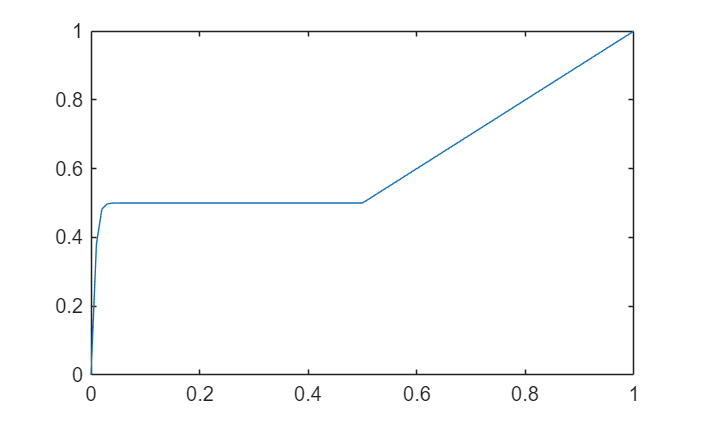

% controlParamsDD = Simulink.data.dictionary.open('controlVariablesData.sldd');
% sectControl = getSection(controlParamsDD,'Design Data');
% Dmin = getValue(getEntry(sectControl,'D_min'));
Dmin = 50;
b = 0.05;

dx = 0.01;
x1 = [0:dx:Dmin/100];
x2 = [Dmin/100+dx:dx:1];
y1 = tanh(x1/b)/tanh(Dmin/100/b)*Dmin/100;
y2 = x2;
x = [x1,x2];
y = [y1,y2];

figure()
plot(x,y)


y = [tanh([0:0.01:Dmin/100]/b)/tanh(Dmin/100/b)*Dmin/100, [Dmin/100+0.01:0.01:1]];

figure()
plot(x,y)

Kp = 35

Kp = 35

Ki = 0.5

Ki = 0.5000

Ts = 0.005

Ts = 0.0050

num_pid = [Kp Ki*Ts-Kp]

num_pid =    35.0000  -34.9975


den_pid = [1 -1]

den_pid =      1    -1


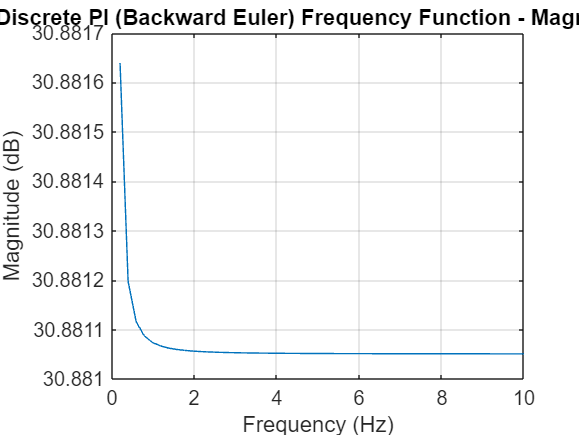


Fs = 1/Ts;
N = 1024; 

[H, W] = freqz(num_pid, den_pid, N, 'whole', Fs);

figure
plot(W(1:N/2+1), 20*log10(abs(H(1:N/2+1))));
grid on;
title('Discrete PI (Backward Euler) Frequency Function - Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 10])

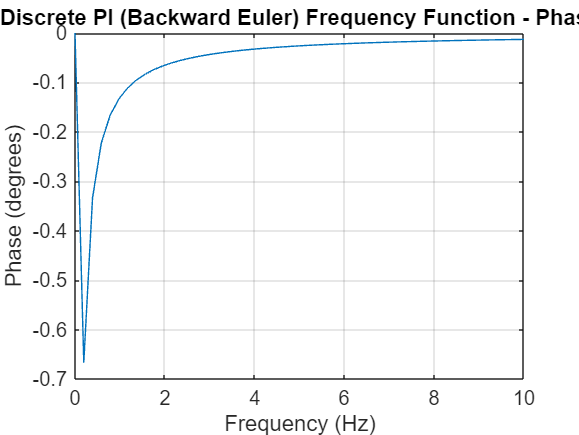


figure
plot(W(1:N/2+1), unwrap(angle(H(1:N/2+1)))*180/pi);
grid on;
title('Discrete PI (Backward Euler) Frequency Function - Phase');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
xlim([0 10])